Let's start with complex polynomial $p(x) := \prod_{i}(x-r_i)$ with roots $r_i\in\mathbb{C}$ :

clear
roots = exp(1i*(2*pi/3)*(0:2)); % example of degree-3
p = poly(roots); % polynomial

We can perform Newton's method (gradient descent) starting from a complex number $z_0$ :


$$z_{k} = z_{k-1} - \frac{f(z_{k-1})}{f'(z_{k-1})},\quad k=1,2,3,\cdots$$


If $\|z_n - r_i\| \le \epsilon$ for large $n$,  threshold $\epsilon$ and $r_i$ , then we color the pixel of $z_0$ on the complex plane as color $i$.

- Here $\epsilon \ll \|r_i - r_j \|,\;\forall i\ne j$ , so the color assignment is unique. (by default $\epsilon = 10^{-6}$)

- It is possible that Newton's method doesn't converge, that is, for all $i$, $\| z_n - r_i \| > \epsilon$, we color pixel $z_0$ by black color.

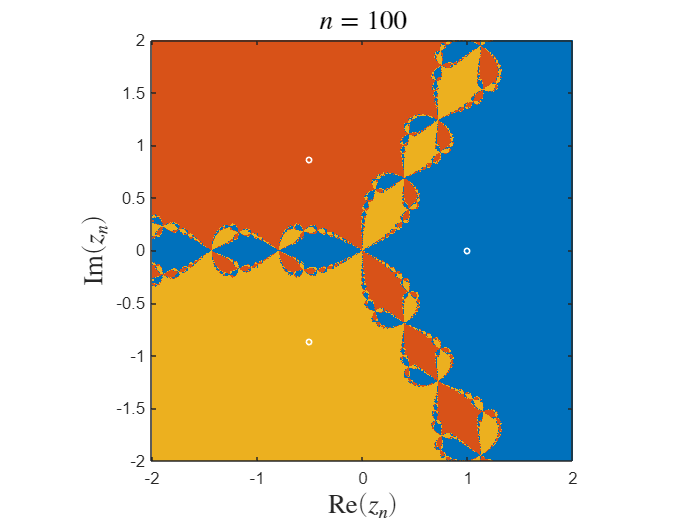

pixels_num = 2^10; % the number of pixels
n = 100; % the number of iteration
epsilon = 1e-6;
% the observation window for z_0
x0 = real(sum(roots))/3;
y0 = imag(sum(roots))/3;
d = 2;
x_v = x0 + linspace(-d,d,pixels_num);
y_v = y0 + linspace(-d,d,pixels_num);
[X0,Y0] = meshgrid(x_v,y_v);
Z0 = X0 + 1i*Y0;

% perform Newton's method, compute z_n
Z = NewtonsMap(Z0,p,n);
Labels =  1:numel(roots); % coloring labels for color_i
Coloring = VoronoiLabeling(Z,roots,Labels, epsilon);

% plot the result
figure
myplot(x_v,y_v,Coloring,roots,n);

Adjust the above parameters to get "near-critical" diagrams:

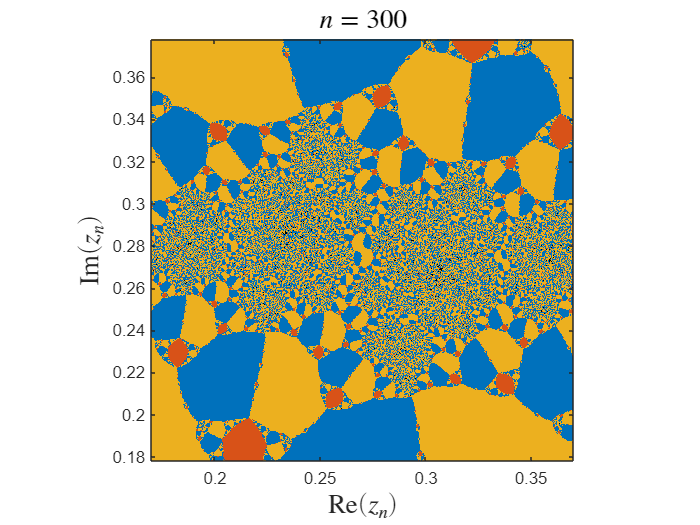

n = 300; % the number of iteration
roots = [1, -1, 0.81+0.83415*1i];
p = poly(roots);
x0 = real(sum(roots))/3;
y0 = imag(sum(roots))/3;
d = 0.1;
x_v = x0 + linspace(-d,d,pixels_num);
y_v = y0 + linspace(-d,d,pixels_num);
[X0,Y0] = meshgrid(x_v,y_v);
Z = NewtonsMap(X0+1i*Y0,p,n);
Coloring = VoronoiLabeling(Z,roots,1:numel(roots), epsilon);

% plot the result
figure;
myplot(x_v,y_v,Coloring,roots,n);

Adjust the above parameters to get "non-convergence" diagrams:

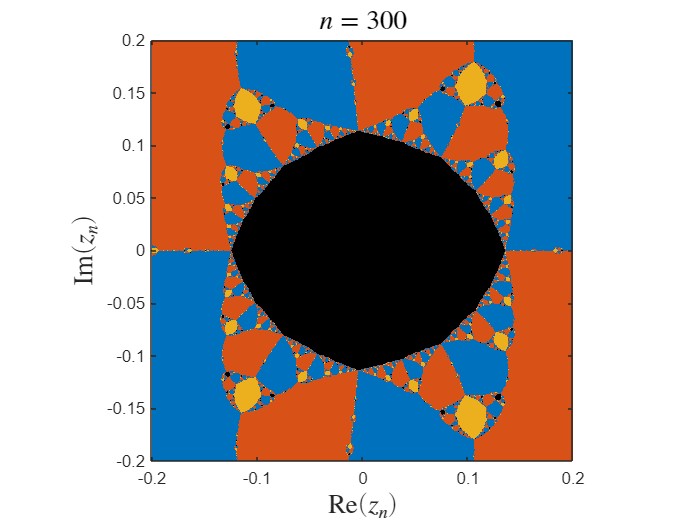

n = 300; % the number of iteration
roots = [0.9+0.6*1i, 0.9-0.6*1i, -1.8];
p = poly(roots);
x0 = real(sum(roots))/3;
y0 = imag(sum(roots))/3;
d = 0.2;
x_v = x0 + linspace(-d,d,pixels_num);
y_v = y0 + linspace(-d,d,pixels_num);
[X0,Y0] = meshgrid(x_v,y_v);
Z = NewtonsMap(X0+1i*Y0,p,n);
Coloring = VoronoiLabeling(Z,roots,1:numel(roots), epsilon);

% plot the result
figure;
myplot(x_v,y_v,Coloring,roots,n);

function Coloring = VoronoiLabeling(Z,roots, Labels, epsilon)
% Z is the matrix for z_n
% roots is the list for r_i
% Target = [x1,x2,x3,...; y1,y2,y3,....]
% Labels: a vector that labels Target 
X = real(Z);
Y = imag(Z);

Dist = zeros(numel(X),numel(roots));
for k = 1:numel(roots)
    r_x = real(roots(k));
    r_y = imag(roots(k));
    Dist(:,k) = sqrt((X(:)-r_x).^2 + (Y(:)-r_y).^2);
end
[Distmin,ind] = min(Dist.');
Coloring = reshape(Labels(ind),size(X));
Coloring(Distmin>=epsilon) = 0;
end

function z = NewtonsMap(z,p,n)
% p: coefficients for polynomial p(x): [p_n,p_{n-1},....,p_1,p_0];
% n: apply this function for n times

q = polyder(p); % coefficients for derivative of polynomial p'(x);
for i = 1:n
    z = z - polyval(p,z)./polyval(q,z);
end
end

function [] = myplot(x_v,y_v,Coloring,roots,n)
fs = 16; % fontsize
imagesc(x_v,y_v,Coloring); % smooth: 'Interpolation', 'bilinear'
hold on
scatter(real(roots),imag(roots),10,[1,1,1],'o','LineWidth',1);
colormap([zeros(1,3);lines(numel(roots))]);
daspect([1,1,1])
xlabel('$\mathrm{Re}(z_n)$','Interpreter','latex','fontsize',fs);
ylabel('$\mathrm{Im}(z_n)$','Interpreter','latex','fontsize',fs);
title(['$n = ',num2str(n),'$'],'Interpreter','latex','fontsize',fs)
set(gca,'YDir','normal')
caxis([0,numel(roots)])
end